n = 7

n = 7

% s = findHalfingSequence(n);
% l = length(s);
s = findSequence(n)
l = length(s)

findShortestPath(39)

p = getNearestPow2(17)

p =     16    32


p = getNearestPow2(16)

p =     16    16


n = 39

n = 39

[p,d] = getNearestPow2(39)

p =     32    64


d =     -7    25


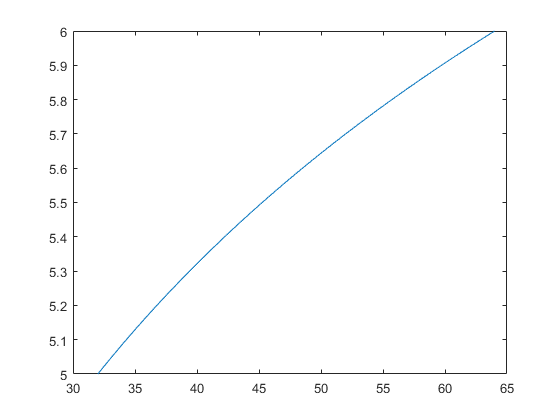

x = p(1):p(2);
y = log2(x);
% y = x - 2 .^ floor(log2(x));
plot( x, y )

T = table([],[],[],[],[],'VariableNames',{'n','i','f','fn','t'});
% for i = d(1):d(2)
%     [f,fi,fn] = getLowestDivisibleFactor2(n+i);
%     T = [T; {n+i,i,f,fn,abs(i)+fi}];
% end
% T = sortrows(T,'f')

T = 33×5 table
    n     i       f       fn    t 
    __    __    ______    __    __

    32    -7         0     1    12
    64    25         0     1    31
    48     9     1.585     3    13
    40     1    2.3219     5     4
    56    17    2.8074     7    20
    36    -3    3.1699     9     5
    44     5    3.4594    11     7
    52    13    3.7004    13    15
    60    21    3.9069    15    23
    34    -5    4.0875    17     6
    38    -1    4.2479    19     2
    42     3    4.3923    21     4
    46     7    4.5236    23     8
    50    11    4.6439    25    12
    54    15    4.7549    27    16
    58    19     4.858    29    20


n = 159

n = 159

[~,T] = searchforpath(n);
T.d = T.n - n;
[~,T.e] = log2(T.fn)

T = 129×6 table
     n       f       fn     t      d     e
    ___    ______    ___    __    ___    _

    128         0      1    38    -31    1
    129    7.0112    129    30    -30    8
    130    6.0224     65    30    -29    7
    131    7.0334    131    28    -28    8
    132    5.0444     33    29    -27    6
    133    7.0553    133    26    -26    8
    134    6.0661     67    26    -25    7
    135    7.0768    135    24    -24    8
    136    4.0875     17    26    -23    5
    137     7.098    137    22    -22    8
    138    6.1085     69    22    -21    7
    139    7.1189    139    20    -20    8
    140    5.1293     35    21    -19    6
    141    7.1396    141    18    -18    8
    142    6.1497     71    18    -17    7
    143    7.1599    143    16    -16    8


% T.d = T.n - n;
% T.p = abs(T.d) + T.fn;
T = sortrows(T,'f')

T = 129×6 table
     n       f       fn     t      d     e
    ___    ______    __    ___    ___    _

    128         0     1     38    -31    1
    256         0     1    105     97    1
    192     1.585     3     39     33    2
    160    2.3219     5      6      1    3
    224    2.8074     7     70     65    3
    144    3.1699     9     19    -15    4
    176    3.4594    11     21     17    4
    208    3.7004    13     53     49    4
    240    3.9069    15     85     81    4
    136    4.0875    17     26    -23    5
    152    4.2479    19     10     -7    5
    168    4.3923    21     12      9    5
    184    4.5236    23     28     25    5
    200    4.6439    25     44     41    5
    216    4.7549    27     60     57    5
    232     4.858    29     76     73    5


function [p,T] = searchforpath(n,T)

arguments
    n
    T = table([],[],[],[],'VariableNames',{'n','f','fn','t'});
end
p  = 0;
[p,d] = getNearestPow2(n);

for i = d(1):d(2)
    x = n+i;
    if any(x==T.n); continue; end
    
    [f,fi,fn] = getLowestDivisibleFactor2(x);
    t = abs(i)+fi;
    T = [T; {x,f,fn,t}];
    
%     if fn ~= 1
%         if ~any(fn==T.n)
%             [~,Tf] = searchforpath(fn);   
%             T = [T;Tf];
%         end  
%     end
end

T = sortrows(T,'n');

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [seq,steps] = findSequence(n)
steps = 0;
seq = [];

% Head down highway log2
if ispow2(n)
    while n > 1
        n = n/2;
        seq = [seq n];
        steps = steps + 1;
    end
end

% Find nearest powers of 2
[fl, dl] = findNearestPow2(n,-1);
[fh, dh] = findNearestPow2(n,1);

% Scan to nearest powers
% Calculate halfing sequences
L = inf;
A = inf;
I = inf;
M = inf;

for i = dl:dh
    if i == 0; continue; end
    a = n+i;
    
    if i > 0
        s = n+1:a;
    else
        s = a:n-1;
    end
    
    s = [s findHalfingSequence(a)];
    
    l = length(s) + abs(i);
    m = min(s);
    
    if m ~= 1
        s = [s findSequence(m)];
    end
    
    if l < L
        A = a; L = l; I = i; M = m;
    end
    disp(a + " (" + l + ") " + ": " + num2str(s))
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function i = findShortestPath(n)
if ispow2(n)
    [~,i] = getlowestfactor(n);
    return
end

[fl, dl] = findNearestPow2(n,-1);
[fh, dh] = findNearestPow2(n,1);


best = inf;
for y = fl:fh
    i = 0;
    
    if y == n; continue; end
    i = abs(n-y);
    [a,b] = getlowestfactor(y);
    i = i + b;
    if a ~= 1
        i = i + findShortestPath(b);
    end
    if i < best
        best = i;
    end
end

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function s = findHalfingSequence(n)
s = [];
while iseven(n)
    n = n/2;
    s = [s n];
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function tf = isodd(n)
tf = ~iseven(n);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function tf = iseven(n)
tf = rem(n,2) == 0;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function tf = ispow2(n)
tf = rem(log2(n),1) == 0;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [n,i] = getlowestfactor(n)
i = 0;
while iseven(n)
    n = n / 2;
    i = i + 1;
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [f,i,n] = getLowestDivisibleFactor2(n)

i = 0;
while iseven(n)
    n = n / 2;
    i = i + 1;
end
f = log2(n);
% f = floor(log2(n));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [p,d] = getNearestPow2(n)

x = log2(n);
hi = 2^ceil(x);
lo = 2^floor(x);
p = [lo hi];
d = p - n;

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [p,d] = findNearestPow2(n,direction)
arguments
    n
    direction {mustBeMember(direction,[-1 1])} = 1
end
x = n;
while ~ispow2(x)
    x = x + direction;
end
p = x;
d = p - n;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%